clear all

k1 = 150;
k2 = 700;
b1 = 15;
b2 = 30;
M1 = 5;
M2 = 20;

A = [0, 0, 1, 0;
    0, 0, 0, 1;
    -k1/M1, k1/M1, -b1/M1, b1/M1;
    k1/M2, -(k1+k2)/M2, b1/M2, -(b1+b2)/M2];
B = [0; 0; 1/M1; 0];
C = [1, 0, 0, 0];
D = 0;

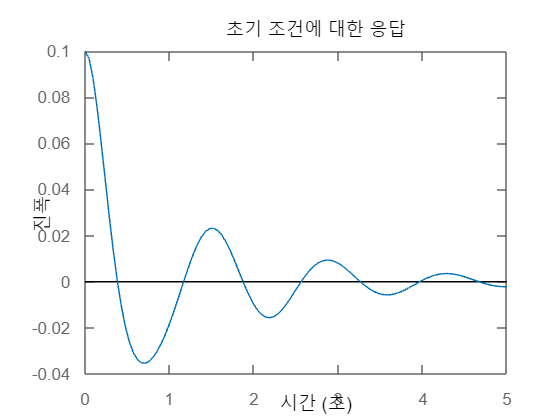

sys = ss(A, B, C, D);
x0 = [0.1, 0, 0, 0];
initial(sys, x0, 5);